% Suunnitellaan samalainen IIR ylipäästösuodin kaikilla neljällä 
% Suunnittelumenetelmällä

% Suunnitteluparametrit:

fs=3000;  % Estokaistan rajataajuus (Hz)
fp=4000;   % Päästökaistan rajataajuus (Hz)
Rp=0.5;   % Päästökaistan maksimivärähtely (dB)
Rs=30;    % Estokaistan minimivaimennus (dB)
Fs=16000; % Näytteenottotaajuus

%Normaalisointi (kerroin 2 Matlabin normalisoinnin vuoksi 2*Wp)

fs_n = 2 * fs/ Fs % == 2 * Ws;

fs_n = 0.3750

fp_n = 2 * fp/ Fs % == 2 * Wp;

fp_n = 0.5000


figure (1)

%Butterworth 
[N, Wn] = buttord(fp_n, fs_n, Rp, Rs)

N = 12

Wn = 0.4633

[b, a] = butter(N, Wn, "high");
subplot(221);
plot_amp_resp(b, a, Fs);
title(sprintf('Butterworth, aste %d', N))

%Cheby I 
[N, Wn] = cheb1ord(fp_n, fs_n, Rp, Rs)

N = 6

Wn = 0.5000

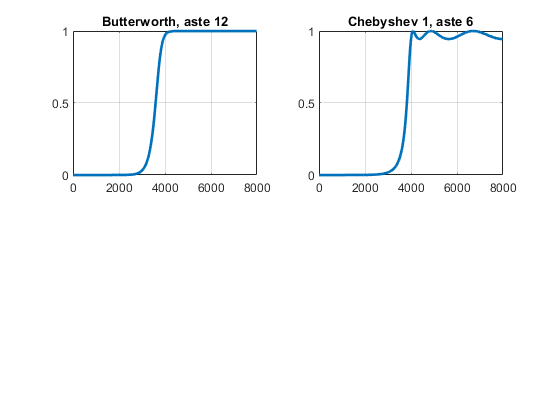

[b, a] = cheby1(N, Rp, Wn, "high");
subplot(222);
plot_amp_resp(b, a, Fs);
title(sprintf('Chebyshev 1, aste %d', N))